clear all;
close all;
addpath('./utils/matlab_code-SSD/');


% Parameters
N = 100;  % Number of points in the time series
num_predict = 1;
optimal_order = 4;  % Set a fixed optimal order for simplicity
L = floor((N-1) / 2);

% Generate sinusoidal signals with exponential decay
t = (1:N)';

rs = 0;
signal1 = 10 * sin(2 * pi * 0.1 * t) %.* exp(-0.01 * t);

signal1 =    5.877852522924732
   9.510565162951535
   9.510565162951536
   5.877852522924733
   0.000000000000001
  -5.877852522924730
  -9.510565162951535
  -9.510565162951536
  -5.877852522924734
  -0.000000000000002


signal2 = 10 * sin(2 * pi * 0.05 * t) %.* exp(-0.01 * t);

signal2 =    3.090169943749474
   5.877852522924732
   8.090169943749475
   9.510565162951535
  10.000000000000000
   9.510565162951536
   8.090169943749475
   5.877852522924733
   3.090169943749475
   0.000000000000001


signal3 = 10 * sin(2 * pi * 0.02 * t) %.* exp(-0.01 * t);

signal3 =    1.253332335643043
   2.486898871648548
   3.681245526846780
   4.817536741017153
   5.877852522924732
   6.845471059286887
   7.705132427757892
   8.443279255020151
   9.048270524660197
   9.510565162951535


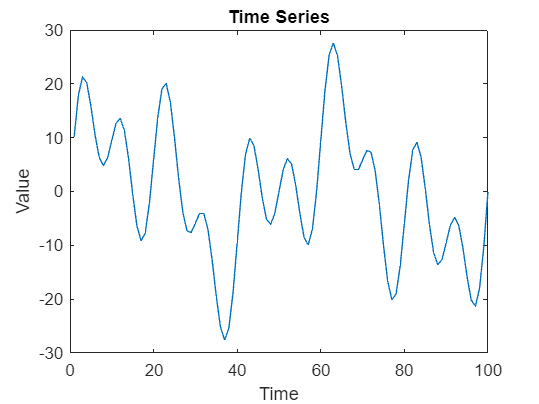


% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Ground truth for point 100
ground_truth = time_series(N);

% Plot the time series
figure;
plot(time_series);
title('Time Series');
xlabel('Time');
ylabel('Value');

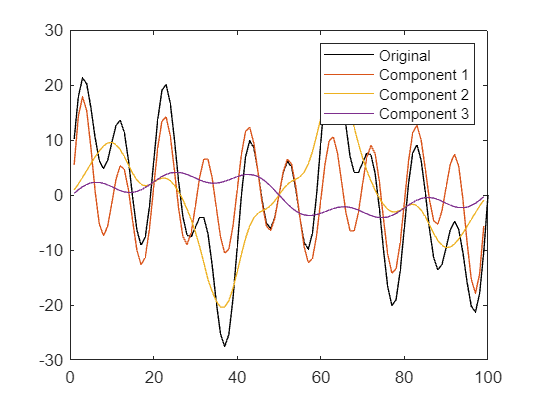


% Prepare storage for predictions
predictions_full = zeros(1, 1);
predictions_components = zeros(1, 1);

% Full time series prediction using AR model
model_full = ar(time_series(1:end-1), optimal_order);  % AR(optimal_order) model
pred_full = forecast(model_full, time_series(1:end-1), num_predict);
predictions_full(1) = pred_full(end);

% Decomposition using SSD
Fs = 10;  % Sampling frequency (you may need to adjust this based on your data)
th = 0.005;  % Threshold for stopping the decomposition
maxNumberofComponents = 3;  % Maximum number of components to extract

H2D = hankel(time_series(1:L),time_series(L:end-1));

SSDcomponents = SSD(time_series(1:end-1), Fs, th, maxNumberofComponents);

% Prepare for component-based prediction
num_components = size(SSDcomponents, 1);
pred_components = zeros(num_components, 1);

figure;
plot(time_series, 'k', 'DisplayName', 'Original');
hold on;

for comp = 1:num_components
    % Extract the component
    component_series = SSDcomponents(comp, :);

    % Plot the component
    plot(component_series, 'DisplayName', ['Component ', num2str(comp)]);

    % Fit AR model to the component and forecast
    model_comp = ar(component_series', optimal_order);
    pred_comp = forecast(model_comp, component_series', num_predict);
    pred_components(comp) = pred_comp(end);
end

hold off;
legend show;


% Sum the predictions of the components
predictions_components(1) = sum(pred_components);

% Display the predictions
disp('Predictions from Full Time Series:');

Predictions from Full Time Series:


disp(predictions_full);

  -0.046654761646280




disp('Predictions from Component Decomposition (SSD):');

Predictions from Component Decomposition (SSD):


disp(predictions_components);

   6.291930136183502




% Compare predictions with ground truth
disp(['Ground truth: ', num2str(ground_truth)]);

Ground truth: -2.3874e-14


disp(['Error (Full Time Series): ', num2str(abs(predictions_full - ground_truth))]);

Error (Full Time Series): 0.046655


disp(['Error (Component Decomposition): ', num2str(abs(predictions_components - ground_truth))]);

Error (Component Decomposition): 6.2919
